# HW 9

Lab work

%% task 1
clear all
% 1D heat flow, steady conditions
n=100; % we divide rode on several parts >> 1mm

Tl=300; % 300 Kelvins (left hand site)
T=zeros(n,1);
%first element has the same temperature as is Tl 
T(1,1)=Tl; % 300 Kelvins

% first iteration
for i=2:(n-1) % last element has T=0K
    T(i,1)=(T(i-1,1)+T(i+1,1))/2;
end

%first iteration 150 = (300+0)/2
% T =
%   300.0000
%   150.0000
%    75.0000
%    37.5000
%    18.7500
%     9.3750
%     4.6875
%     2.3438

% second iteration
T=zeros(n,1); % zero Kelvin
T(1,1)=Tl; % 300 Kelvins
for iter=1:2    % two iteration
    for i=2:(n-1)
        T(i,1)=(T(i-1,1)+T(i+1,1))/2;
    end
end
% second iteration (300+75)/2 = 187.5
% T =
%   300.0000
%   187.5000
%   112.5000
%    65.6250
%    37.5000
%    21.0938
%    11.7188
%     6.4453

%How much is T(2,1) after 10, 100, 1000 iterations?
T=zeros(n,1);
T(1,1)=Tl; % 300 Kelvins
for iter=1:10    % numb. of iterations
    for i=2:(n-1)
        T(i,1)=(T(i-1,1)+T(i+1,1))/2;
    end
    fprintf('%4i  %10.6f\n',iter,T(2,1)) % second element
end

   1  150.000000
   2  187.500000
   3  206.250000
   4  217.968750
   5  226.171875
   6  232.324219
   7  237.158203
   8  241.085815
   9  244.358826
  10  247.140884


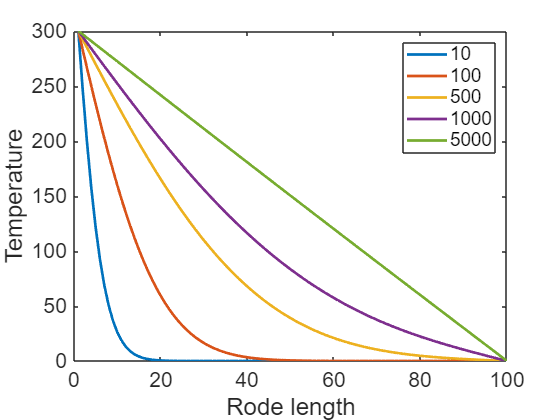


% How mwany steps are needed to obtain constant gradient >> linear relation?
% number of iteartions "presenet" the time elapse.

% plot T after 100 1000 10000 100000 and 1000000 iterartion

Tsave=NaN(n,5); % save solution for 100 1000 10000 100000 and 1000000 iterartion

T=zeros(n,1);
T(1,1)=Tl; % 300 Kelvins
for iter=1:5000    % num. of iterations
    for i=2:(n-1)
        T(i,1)=(T(i-1,1)+T(i+1,1))/2;
    end
    
    if iter==10;Tsave(:,1)=T;end
    if iter==100;Tsave(:,2)=T;end
    if iter==500;Tsave(:,3)=T;end
    if iter==1000;Tsave(:,4)=T;end
    if iter==5000;Tsave(:,5)=T;end

end

% plot
plot(Tsave,'LineWidth',2)
ax=gca; % Get handle to current axis.
%xlim([-0.1 3.2])
%ylim([-1.2 1.2]) % Y axis limit
ax.XAxis.FontSize = 16; % font size of X axis
ax.YAxis.FontSize = 16; % font size of Y axis
%ytickformat('%.2f'); % two decimal placaes for number as Y axis
ylabel('Temperature','FontSize',18); % label at Y axis
xlabel('Rode length','FontSize',18); % abel at X axis, see \alpha !!!

legend('10','100','500','1000','5000','FontSize',14)

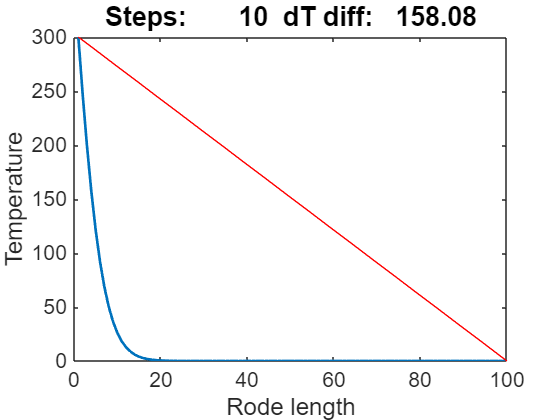


% saveas(gcf,'heat1Dsteady.png')


%% task2
% drawnow dynamic graph
% 1D heat flow, steady conditions, 

n=100; % we divide rode on several parts >> 1mm

T=zeros(n,1);
Tl=300; % 300 Kelvins (left hand site)

dd=Tl/(n-1);
Tfinal=(300:-dd:0)';

% plot T after 100 1000 10000 100000 and 1000000 iterartion

%draw line - redline, steady flow
x = [1 100];
y = [300 0];

T=zeros(n,1);
T(1,1)=Tl; % 300 Kelvins
for iter=1:10    % num. of iterations
    for i=2:(n-1)
        T(i,1)=(T(i-1,1)+T(i+1,1))/2;
    end
    % difference
    df=sqrt(sum((T-Tfinal).^2)/(n-1));
    %
    plot(T,'LineWidth',2)
    line(x,y,'Color','red')
    ax=gca; % Get handle to current axis.
    %xlim([-0.1 3.2])
    %ylim([-1.2 1.2]) % Y axis limit
    ax.XAxis.FontSize = 16; % font size of X axis
    ax.YAxis.FontSize = 16; % font size of Y axis
    %ytickformat('%.2f'); % two decimal placaes for number as Y axis
    ylabel('Temperature','FontSize',18); % label at Y axis
    xlabel('Rode length','FontSize',18);
    mytitle=sprintf('Steps: %8i  dT diff: %8.2f',iter,df);
    title(mytitle,'FontSize',20)
    drawnow
end

Homework

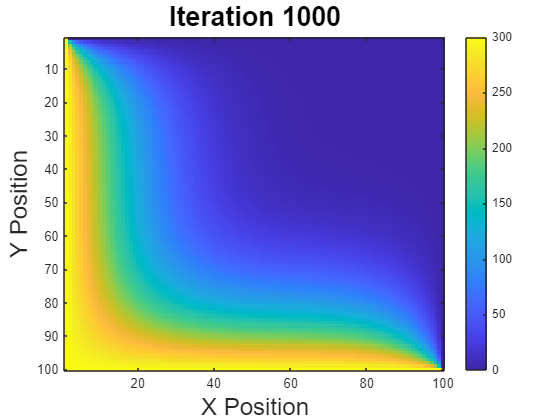

%% HW
% Parameters
n = 100;
T = zeros(n, n); % Grid

% Boundaryes
T(:, 1) = 300; % From left to right
%T(:, end) = 300; % From right to left
%T(1, :) = 300; % From top to bottom
T(end, :) = 300; % From bottom to top

% Create figure for animation
figure;
h = imagesc(T); % Initial plot
colorbar;
clim([0, 300]); % Fixes color scale
xlabel('X Position', 'FontSize', 18);
ylabel('Y Position', 'FontSize', 18);
title('2D Heat Conduction', 'FontSize', 20);

max_iter = 1000;
for iter = 1:max_iter
    T_old = T; % Save the old temperature distribution
    
    for i = 2:n-1
        for j = 2:n-1
            T(i, j) = (T_old(i-1, j) + T_old(i+1, j) + T_old(i, j-1) + T_old(i, j+1)) / 4;
        end
    end
    
    % imagesc(T);
    set(h, 'CData', T); % Update
    title(sprintf('Iteration %d', iter), 'FontSize', 20);
    drawnow;
    % pause(0.01); % Short pause to force plot update
end